## **Worked Example 7.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input the A,B,C and D matrices
A = [0, 1; -4, -2];
B = [0; 1];
C = [1 0];
D = [0];

% Create a state-space system
sys = ss(A, B, C, D);

% Calculate the eigenvalues, damping ratio and natural frequency
damp(sys);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 1.73e+00i     5.00e-01       2.00e+00         1.00e+00    
 -1.00e+00 - 1.73e+00i     5.00e-01       2.00e+00         1.00e+00    



% Input the desired eigenvalue locations
P = [(-3 + sqrt(7) * i); (-3 - sqrt(7) * i)]

P =   -3.0000 + 2.6458i
  -3.0000 - 2.6458i



% Calculate the state feedback gain vector K
K = -1 * place(A, B, P) % u = -Kx in MATLAB

K =   -12.0000   -4.0000



% Create the closed loop system
Acl = A + B * K

Acl =          0    1.0000
  -16.0000   -6.0000



sys_cl = ss(Acl, B, C, D)


sys_cl =
 
  A = 
        x1   x2
   x1    0    1
   x2  -16   -6
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Prope

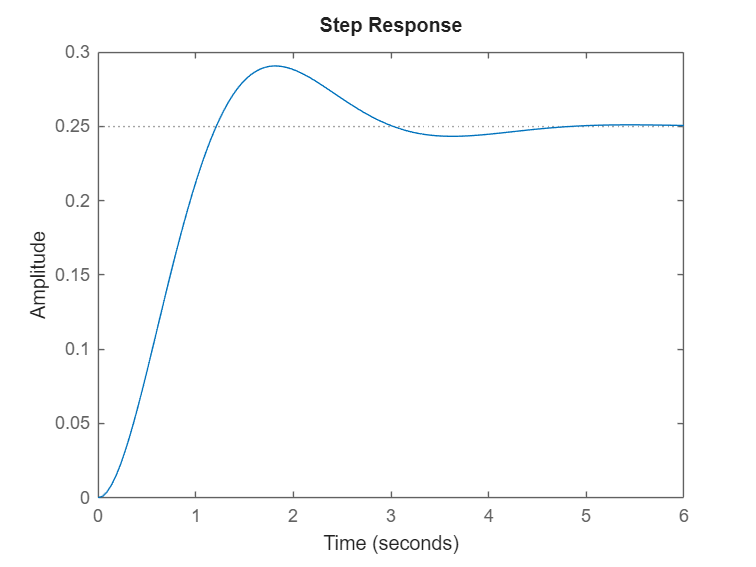


step(sys)


stepinfo(sys)

ans = struct with fields:
         RiseTime: 0.8195
    TransientTime: 4.0379
     SettlingTime: 4.0379
      SettlingMin: 0.2329
      SettlingMax: 0.2907
        Overshoot: 16.2929
       Undershoot: 0
             Peak: 0.2907
         PeakTime: 1.7960


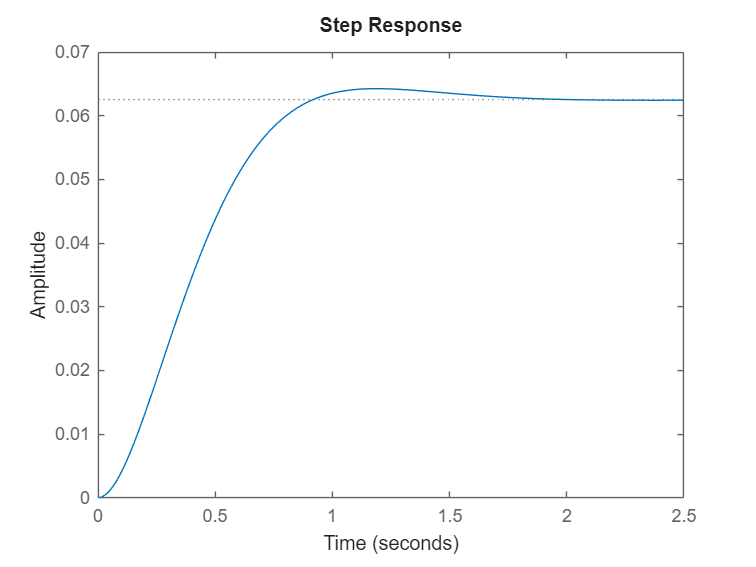


step(sys_cl)


stepinfo(sys_cl)

ans = struct with fields:
         RiseTime: 0.5721
    TransientTime: 1.4356
     SettlingTime: 1.4356
      SettlingMin: 0.0566
      SettlingMax: 0.0643
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.0643
         PeakTime: 1.1820



% Calculate the eigenvalues, damping ratio and natural frequency
damp(sys_cl);

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.00e+00 + 2.65e+00i     7.50e-01       4.00e+00         3.33e-01    
 -3.00e+00 - 2.65e+00i     7.50e-01       4.00e+00         3.33e-01    
